# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

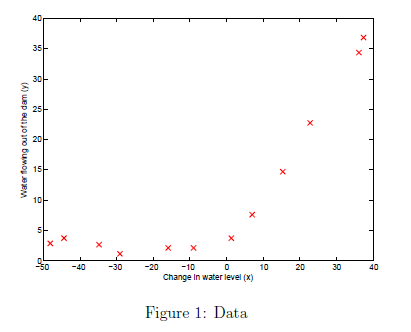

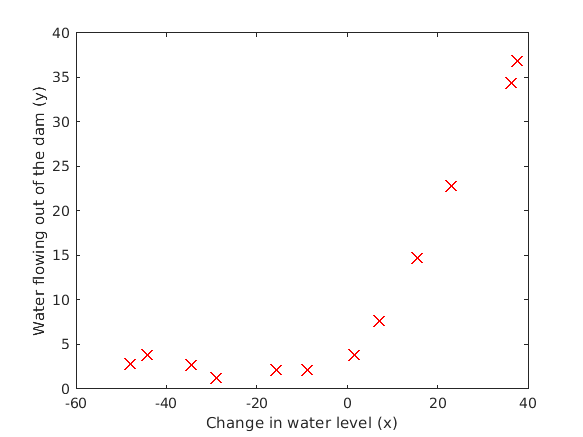

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment

load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

Cost at theta = [1 ; 1]: 303.993192

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overtting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\mathrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\mathrm{for}\;\;j=0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     4 | Cost: 2.237391e+01


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

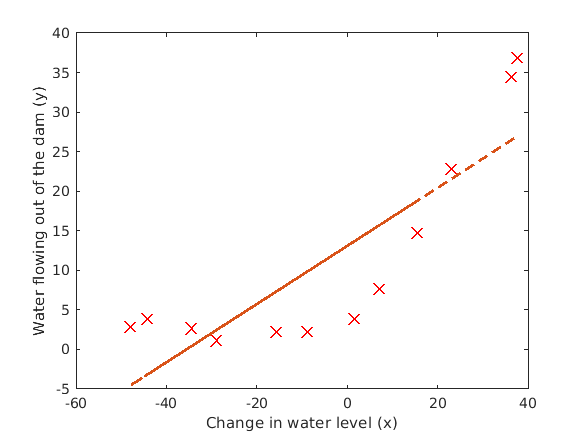

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');

ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

Dataset size: 1
Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00


theta =     0.0084
   -0.1334


*********************************************************************************
Dataset size: 2
Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32


theta =     3.2932
    0.0727


*********************************************************************************
Dataset size: 3
Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     3 | Cost: 3.286595e+00


theta =    14.1550
    0.5391


*********************************************************************************
Dataset size: 4
Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.842916e+00
Iteration     7 | Cost: 2.842916e+00
Iteration     8 | Cost: 2.842770e+00
Iteration     9 | Cost: 2.842731e+00
Iteration    10 | Cost: 2.842729e+00
Iteration    11 | Cost: 2.842678e+00


theta =    14.6243
    0.5599


*********************************************************************************
Dataset size: 5
Iteration     1 | Cost: 1.592641e+02
Iteration     2 | Cost: 2.404966e+01
Iteration     3 | Cost: 2.354137e+01
Iteration     4 | Cost: 2.281160e+01
Iteration     5 | Cost: 2.276969e+01
Iteration     6 | Cost: 2.224060e+01
Iteration     7 | Cost: 1.920606e+01
Iteration     8 | Cost: 1.475292e+01
Iteration     9 | Cost: 1.430565e+01
Iteration    10 | Cost: 1.388881e+01
Iteration    11 | Cost: 1.327330e+01
Iteration    12 | Cost: 1.323519e+01
Iteration    13 | Cost: 1.319411e+01
Iteration    14 | Cost: 1.317355e+01
Iteration    15 | Cost: 1.315411e+01
Iteration    16 | Cost: 1.315405e+01
Iteration    17 | Cost: 1.315405e+01
Iteration    18 | Cost: 1.315405e+01
Iteration    19 | Cost: 1.315405e+01
Iteration    20 | Cost: 1.315405e+01
Iteration    21 | Cost: 1.315405e+01
Iteration    22 | Cost: 1.315405e+01


theta =    17.2138
    0.4497


*********************************************************************************
Dataset size: 6
Iteration     1 | Cost: 1.531141e+02
Iteration     2 | Cost: 1.350947e+02
Iteration     3 | Cost: 1.137334e+02
Iteration     4 | Cost: 4.404199e+01
Iteration     5 | Cost: 2.957435e+01
Iteration     6 | Cost: 2.719561e+01
Iteration     7 | Cost: 1.949283e+01
Iteration     8 | Cost: 1.949128e+01
Iteration     9 | Cost: 1.945708e+01
Iteration    10 | Cost: 1.944472e+01
Iteration    11 | Cost: 1.944472e+01
Iteration    12 | Cost: 1.944471e+01
Iteration    13 | Cost: 1.944453e+01
Iteration    14 | Cost: 1.944425e+01
Iteration    15 | Cost: 1.944411e+01
Iteration    16 | Cost: 1.944396e+01
Iteration    17 | Cost: 1.944396e+01
Iteration    18 | Cost: 1.944396e+01
Iteration    19 | Cost: 1.944396e+01
Iteration    20 | Cost: 1.944396e+01
Iteration    21 | Cost: 1.944396e+01
Iteration    22 | Cost: 1.944396e+01
Iteration    23 | Cost: 1.944396e+01
Iteration    24 | Cost: 1.944396e+01
Iteration    2

theta =    15.4049
    0.4574


*********************************************************************************
Dataset size: 7
Iteration     1 | Cost: 1.383936e+02
Iteration     2 | Cost: 1.210275e+02
Iteration     3 | Cost: 1.013004e+02
Iteration     4 | Cost: 3.457729e+01
Iteration     5 | Cost: 2.808710e+01
Iteration     6 | Cost: 2.732288e+01
Iteration     7 | Cost: 2.011513e+01
Iteration     8 | Cost: 2.011508e+01
Iteration     9 | Cost: 2.010693e+01
Iteration    10 | Cost: 2.010640e+01
Iteration    11 | Cost: 2.010629e+01
Iteration    12 | Cost: 2.010382e+01
Iteration    13 | Cost: 2.009852e+01
Iteration    14 | Cost: 2.009852e+01
Iteration    15 | Cost: 2.009852e+01
Iteration    16 | Cost: 2.009852e+01


theta =    14.2668
    0.4368


*********************************************************************************
Dataset size: 8
Iteration     1 | Cost: 1.237772e+02
Iteration     2 | Cost: 1.202532e+02
Iteration     3 | Cost: 1.195134e+02
Iteration     4 | Cost: 9.334231e+01
Iteration     5 | Cost: 4.813526e+01
Iteration     6 | Cost: 2.677826e+01
Iteration     7 | Cost: 1.953374e+01
Iteration     8 | Cost: 1.831672e+01
Iteration     9 | Cost: 1.817286e+01
Iteration    11 | Cost: 1.817286e+01


theta =    14.6234
    0.4231


*********************************************************************************
Dataset size: 9
Iteration     1 | Cost: 1.089984e+02
Iteration     2 | Cost: 1.064701e+02
Iteration     3 | Cost: 1.054742e+02
Iteration     4 | Cost: 2.266786e+01
Iteration     5 | Cost: 2.266786e+01
Iteration     6 | Cost: 2.266758e+01
Iteration     7 | Cost: 2.260941e+01


theta =    13.2966
    0.4130


*********************************************************************************
Dataset size: 10
Iteration     1 | Cost: 1.108611e+02
Iteration     2 | Cost: 2.497543e+01
Iteration     3 | Cost: 2.496421e+01
Iteration     4 | Cost: 2.494837e+01
Iteration     5 | Cost: 2.493176e+01
Iteration     6 | Cost: 2.490651e+01
Iteration     7 | Cost: 2.474375e+01
Iteration     8 | Cost: 2.326167e+01
Iteration     9 | Cost: 2.326167e+01
Iteration    10 | Cost: 2.326164e+01
Iteration    11 | Cost: 2.326146e+01
Iteration    12 | Cost: 2.326146e+01
Iteration    13 | Cost: 2.326146e+01
Iteration    14 | Cost: 2.326146e+01
Iteration    15 | Cost: 2.326146e+01
Iteration    16 | Cost: 2.326146e+01
Iteration    17 | Cost: 2.326146e+01
Iteration    18 | Cost: 2.326146e+01
Iteration    19 | Cost: 2.326146e+01
Iteration    20 | Cost: 2.326146e+01
Iteration    21 | Cost: 2.326146e+01
Iteration    22 | Cost: 2.326146e+01
Iteration    23 | Cost: 2.326146e+01
Iteration    24 | Cost: 2.326146e+01
Iteration    

theta =    13.8537
    0.3778


*********************************************************************************
Dataset size: 11
Iteration     1 | Cost: 1.023394e+02
Iteration     2 | Cost: 2.443039e+01
Iteration     3 | Cost: 2.443033e+01
Iteration     4 | Cost: 2.442972e+01
Iteration     5 | Cost: 2.441042e+01
Iteration     6 | Cost: 2.435852e+01
Iteration     7 | Cost: 2.431735e+01
Iteration     8 | Cost: 2.431733e+01
Iteration     9 | Cost: 2.431727e+01
Iteration    10 | Cost: 2.431725e+01
Iteration    11 | Cost: 2.431725e+01


theta =    12.9372
    0.3634


*********************************************************************************
Dataset size: 12
Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     4 | Cost: 2.237391e+01


theta =    13.0879
    0.3678


*********************************************************************************


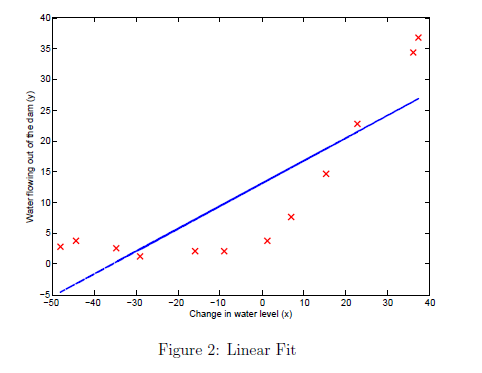

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

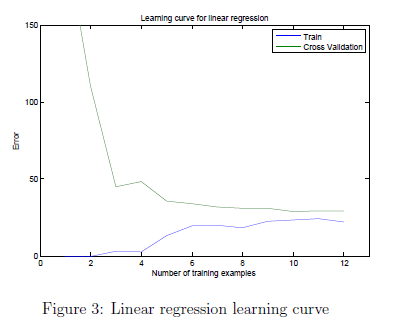

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

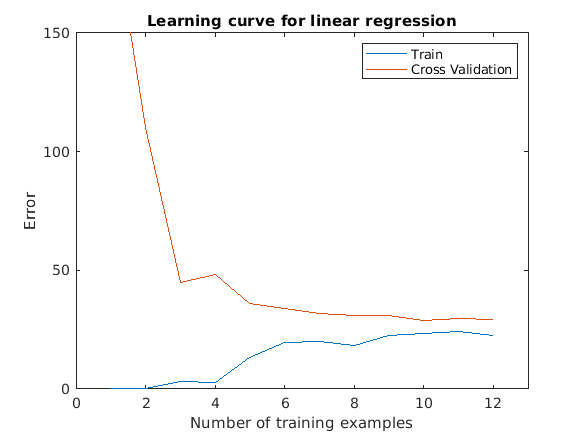

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')

xlabel('Number of training examples')
ylabel('Error')

# Training Examples	Train Error	Cross Validation Error


axis([0 13 0 150])

fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% % Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411543e-01
Iteration    11 | Cost: 7.963444e-01
Iteration    12 | Cost: 7.528112e-01
Iteration    13 | Cost: 6.880751e-01
Iteration    14 | Cost: 5.714607e-01
Iteration    15 | Cost: 5.378361e-01
Iteration    16 | Cost: 4.500706e-01
Iteration    17 | Cost: 4.476781e-01
Iteration    18 | Cost: 4.323836e-01
Iteration    19 | Cost: 3.753054e-01
Iteration    20 | Cost: 3.694780e-01
Iteration    21 | Cost: 3.575323e-01
Iteration    22 | Cost: 3.527283e-01
Iteration    23 | Cost: 3.404259e-01
Iteration    24 | Cost: 3.397391e-01
Iteration    25 | Cost: 3.385740e-01
Iteration    26 | Cost: 3.342204e-01
Iteration    27 | Cost: 3.319424e-01
I

    After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

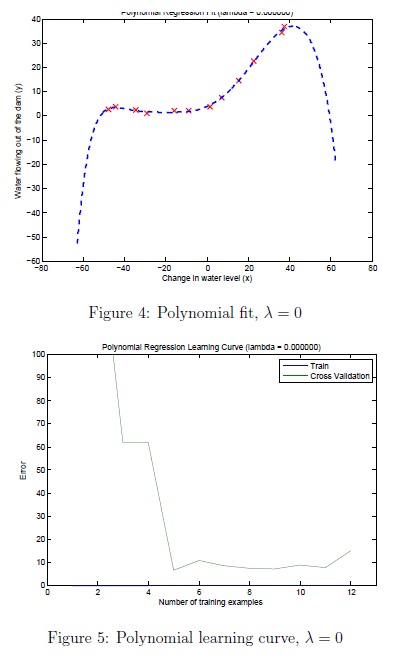

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

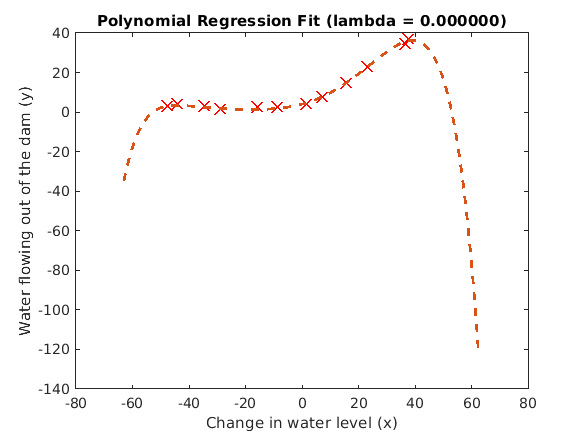

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

plot(1:m, error_train, 1:m, error_val);

Dataset size: 1
Lambda Value:0.000000
Iteration     1 | Cost: 3.386454e-01
Iteration     2 | Cost: 9.860761e-32
Iteration     4 | Cost: 0.000000e+00


theta =     0.6989
   -0.2531
   -0.5278
    0.1274
   -0.4936
    0.2143
   -0.4130
    0.2408
   -0.3554


*********************************************************************************
Dataset size: 2
Lambda Value:0.000000
Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 4.560072e-11
Iteration     5 | Cost: 4.560059e-11
Iteration     6 | Cost: 2.309960e-11
Iteration     7 | Cost: 1.551252e-14
Iteration     8 | Cost: 1.550239e-14
Iteration     9 | Cost: 7.917902e-15
Iteration    10 | Cost: 5.482829e-17
Iteration    11 | Cost: 3.321856e-17
Iteration    12 | Cost: 4.062935e-18
Iteration    13 | Cost: 3.711338e-18
Iteration    14 | Cost: 9.611423e-19
Iteration    15 | Cost: 5.369185e-29
Iteration    16 | Cost: 1.232595e-32
Iteration    17 | Cost: 0.000000e+00


theta =     0.5958
   -0.0733
   -0.6941
    0.2475
   -0.5432
    0.2515
   -0.4021
    0.2340
   -0.3222


*********************************************************************************
Dataset size: 3
Lambda Value:0.000000
Iteration     1 | Cost: 3.023381e+01
Iteration     2 | Cost: 9.745401e-01
Iteration     3 | Cost: 4.827305e-01
Iteration     4 | Cost: 1.170249e-02
Iteration     5 | Cost: 9.696908e-04
Iteration     6 | Cost: 5.299258e-04
Iteration     7 | Cost: 1.985836e-04
Iteration     8 | Cost: 6.032119e-05
Iteration     9 | Cost: 6.225212e-07
Iteration    10 | Cost: 3.894758e-07
Iteration    11 | Cost: 7.703724e-08
Iteration    12 | Cost: 5.688321e-08
Iteration    13 | Cost: 5.385450e-09
Iteration    14 | Cost: 1.603656e-10
Iteration    15 | Cost: 1.516867e-11
Iteration    16 | Cost: 9.627464e-12
Iteration    17 | Cost: 2.794098e-12
Iteration    18 | Cost: 7.766256e-13
Iteration    19 | Cost: 1.571268e-13
Iteration    20 | Cost: 2.248293e-16
Iteration    21 | Cost: 5.079315e-17
Iteration    22 | Cost: 1.499571e-17
Iteration    23 | Cost: 3.850977e-18
Iteration    24 | Cost: 8.299

theta =     6.3942
    6.0725
    6.1249
    5.6590
    2.6152
    5.0238
    0.2492
    4.2528
   -1.0254


*********************************************************************************
Dataset size: 4
Lambda Value:0.000000
Iteration     1 | Cost: 7.960488e-01
Iteration     2 | Cost: 2.114171e-01
Iteration     3 | Cost: 2.702642e-02
Iteration     4 | Cost: 3.974598e-19
Iteration     5 | Cost: 3.036884e-25
Iteration     6 | Cost: 1.125879e-25
Iteration     7 | Cost: 7.950239e-28
Iteration     8 | Cost: 6.303492e-28


theta =     6.5574
    7.5559
    6.9020
    5.1406
    1.9603
    3.8532
   -0.9940
    3.0128
   -2.2925


*********************************************************************************
Dataset size: 5
Lambda Value:0.000000
Iteration     1 | Cost: 9.143237e+01
Iteration     2 | Cost: 2.762462e+01
Iteration     3 | Cost: 3.042180e+00
Iteration     4 | Cost: 1.453025e+00
Iteration     5 | Cost: 1.272768e-01
Iteration     6 | Cost: 1.141820e-01
Iteration     7 | Cost: 6.971294e-02
Iteration     8 | Cost: 6.732499e-02
Iteration     9 | Cost: 6.408738e-02
Iteration    10 | Cost: 6.065215e-02
Iteration    11 | Cost: 5.488028e-02
Iteration    12 | Cost: 4.810865e-02
Iteration    13 | Cost: 4.141165e-02
Iteration    14 | Cost: 3.621003e-02
Iteration    15 | Cost: 3.342304e-02
Iteration    16 | Cost: 3.276916e-02
Iteration    17 | Cost: 3.197599e-02
Iteration    18 | Cost: 3.051728e-02
Iteration    19 | Cost: 3.027669e-02
Iteration    20 | Cost: 2.924438e-02
Iteration    21 | Cost: 2.874093e-02
Iteration    22 | Cost: 2.833021e-02
Iteration    23 | Cost: 2.749501e-02
Iteration    24 | Cost: 2.708

theta =    10.4184
    8.3481
    5.5791
    5.1724
    2.6397
    2.0801
    1.0140
    0.1545
    0.4297


*********************************************************************************
Dataset size: 6
Lambda Value:0.000000
Iteration     1 | Cost: 6.685771e+01
Iteration     2 | Cost: 1.216701e+01
Iteration     3 | Cost: 1.795979e+00
Iteration     4 | Cost: 6.292963e-01
Iteration     5 | Cost: 2.225698e-01
Iteration     6 | Cost: 5.075312e-02
Iteration     7 | Cost: 4.971823e-02
Iteration     8 | Cost: 4.887207e-02
Iteration     9 | Cost: 4.848298e-02
Iteration    10 | Cost: 4.805701e-02
Iteration    11 | Cost: 4.762072e-02
Iteration    12 | Cost: 4.708531e-02
Iteration    13 | Cost: 4.655855e-02
Iteration    14 | Cost: 4.629137e-02
Iteration    15 | Cost: 4.627522e-02
Iteration    16 | Cost: 4.608175e-02
Iteration    17 | Cost: 4.589530e-02
Iteration    18 | Cost: 4.567885e-02
Iteration    19 | Cost: 4.558348e-02
Iteration    20 | Cost: 4.525438e-02
Iteration    21 | Cost: 4.401673e-02
Iteration    22 | Cost: 4.355375e-02
Iteration    23 | Cost: 4.348018e-02
Iteration    24 | Cost: 4.316

theta =     9.2662
    4.9375
    9.1351
   11.2127
   -2.0581
    2.9504
    0.2650
   -3.9739
    2.6168


*********************************************************************************
Dataset size: 7
Lambda Value:0.000000
Iteration     1 | Cost: 7.107198e+01
Iteration     2 | Cost: 4.715009e+00
Iteration     3 | Cost: 2.533424e+00
Iteration     4 | Cost: 1.508308e+00
Iteration     5 | Cost: 1.458474e+00
Iteration     6 | Cost: 1.300523e+00
Iteration     7 | Cost: 1.150698e+00
Iteration     8 | Cost: 1.052860e+00
Iteration     9 | Cost: 9.122515e-01
Iteration    10 | Cost: 8.168641e-01
Iteration    11 | Cost: 7.966073e-01
Iteration    12 | Cost: 7.186194e-01
Iteration    13 | Cost: 5.237808e-01
Iteration    14 | Cost: 4.921634e-01
Iteration    15 | Cost: 3.741185e-01
Iteration    16 | Cost: 3.628545e-01
Iteration    17 | Cost: 3.121972e-01
Iteration    18 | Cost: 2.896770e-01
Iteration    19 | Cost: 2.727791e-01
Iteration    20 | Cost: 2.430254e-01
Iteration    21 | Cost: 2.335362e-01
Iteration    22 | Cost: 2.272544e-01
Iteration    23 | Cost: 2.132905e-01
Iteration    24 | Cost: 1.928

theta =    10.7521
   12.7691
   11.8685
   -2.2487
  -11.8459
    4.0138
    1.5183
    3.5569
    9.5966


*********************************************************************************
Dataset size: 8
Lambda Value:0.000000
Iteration     1 | Cost: 6.233475e+01
Iteration     2 | Cost: 6.252861e+00
Iteration     3 | Cost: 3.386639e+00
Iteration     4 | Cost: 1.849186e+00
Iteration     5 | Cost: 1.488263e+00
Iteration     6 | Cost: 1.304655e+00
Iteration     7 | Cost: 1.227710e+00
Iteration     8 | Cost: 1.135255e+00
Iteration     9 | Cost: 1.035629e+00
Iteration    10 | Cost: 9.292646e-01
Iteration    11 | Cost: 7.582864e-01
Iteration    12 | Cost: 6.949027e-01
Iteration    13 | Cost: 4.850758e-01
Iteration    14 | Cost: 4.396008e-01
Iteration    15 | Cost: 3.164280e-01
Iteration    16 | Cost: 1.449082e-01
Iteration    17 | Cost: 1.309203e-01
Iteration    18 | Cost: 1.200797e-01
Iteration    19 | Cost: 1.099894e-01
Iteration    20 | Cost: 1.069281e-01
Iteration    21 | Cost: 1.045676e-01
Iteration    22 | Cost: 1.042434e-01
Iteration    23 | Cost: 1.028115e-01
Iteration    24 | Cost: 1.023

theta =    11.3277
   13.1355
    7.8369
   -2.2912
   -2.0743
    0.6940
    2.3084
    4.6816
    1.4537


*********************************************************************************
Dataset size: 9
Lambda Value:0.000000
Iteration     1 | Cost: 5.922449e+01
Iteration     2 | Cost: 2.724806e+00
Iteration     3 | Cost: 1.507147e+00
Iteration     4 | Cost: 1.432124e+00
Iteration     5 | Cost: 1.346546e+00
Iteration     6 | Cost: 1.186548e+00
Iteration     7 | Cost: 1.080899e+00
Iteration     8 | Cost: 7.347683e-01
Iteration     9 | Cost: 6.810485e-01
Iteration    10 | Cost: 4.738682e-01
Iteration    11 | Cost: 4.507334e-01
Iteration    12 | Cost: 4.357202e-01
Iteration    13 | Cost: 4.349644e-01
Iteration    14 | Cost: 4.266373e-01
Iteration    15 | Cost: 4.237060e-01
Iteration    16 | Cost: 4.131325e-01
Iteration    17 | Cost: 4.059752e-01
Iteration    18 | Cost: 3.966538e-01
Iteration    19 | Cost: 3.916916e-01
Iteration    20 | Cost: 3.911993e-01
Iteration    21 | Cost: 3.855238e-01
Iteration    22 | Cost: 3.797465e-01
Iteration    23 | Cost: 3.771098e-01
Iteration    24 | Cost: 3.693

theta =    10.9592
   12.2737
   14.5076
    2.6726
  -18.9798
  -11.2716
   12.7941
   15.0226
    4.1735


*********************************************************************************
Dataset size: 10
Lambda Value:0.000000
Iteration     1 | Cost: 5.599132e+01
Iteration     2 | Cost: 4.583568e+00
Iteration     3 | Cost: 4.311901e+00
Iteration     4 | Cost: 2.585710e+00
Iteration     5 | Cost: 1.660674e+00
Iteration     6 | Cost: 1.483926e+00
Iteration     7 | Cost: 1.288619e+00
Iteration     8 | Cost: 1.203498e+00
Iteration     9 | Cost: 9.994751e-01
Iteration    10 | Cost: 7.519726e-01
Iteration    11 | Cost: 7.150079e-01
Iteration    12 | Cost: 5.787843e-01
Iteration    13 | Cost: 5.450867e-01
Iteration    14 | Cost: 4.957827e-01
Iteration    15 | Cost: 4.925067e-01
Iteration    16 | Cost: 4.604774e-01
Iteration    17 | Cost: 4.528128e-01
Iteration    18 | Cost: 4.279772e-01
Iteration    19 | Cost: 4.253460e-01
Iteration    20 | Cost: 4.081528e-01
Iteration    21 | Cost: 3.947841e-01
Iteration    22 | Cost: 3.922638e-01
Iteration    23 | Cost: 3.820951e-01
Iteration    24 | Cost: 3.78

theta =    11.0917
   11.5665
   13.2729
    7.1985
  -11.1743
  -10.1182
    8.5430
    4.4679
   -3.7212


*********************************************************************************
Dataset size: 11
Lambda Value:0.000000
Iteration     1 | Cost: 7.186879e+01
Iteration     2 | Cost: 2.278130e+01
Iteration     3 | Cost: 4.970159e+00
Iteration     4 | Cost: 1.355413e+00
Iteration     5 | Cost: 1.252814e+00
Iteration     6 | Cost: 1.187924e+00
Iteration     7 | Cost: 1.158307e+00
Iteration     8 | Cost: 1.038309e+00
Iteration     9 | Cost: 9.137843e-01
Iteration    10 | Cost: 8.985617e-01
Iteration    11 | Cost: 8.340804e-01
Iteration    12 | Cost: 8.019734e-01
Iteration    13 | Cost: 7.850833e-01
Iteration    14 | Cost: 6.376542e-01
Iteration    15 | Cost: 4.907139e-01
Iteration    16 | Cost: 3.597927e-01
Iteration    17 | Cost: 3.455701e-01
Iteration    18 | Cost: 3.300287e-01
Iteration    19 | Cost: 3.278026e-01
Iteration    20 | Cost: 3.191068e-01
Iteration    21 | Cost: 3.188925e-01
Iteration    22 | Cost: 3.170076e-01
Iteration    23 | Cost: 3.101588e-01
Iteration    24 | Cost: 3.07

theta =    11.1419
   11.4858
   16.2888
    9.5532
  -22.2953
  -19.1127
   19.0446
   13.4897
   -3.7732


*********************************************************************************
Dataset size: 12
Lambda Value:0.000000
Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411543e-01
Iteration    11 | Cost: 7.963444e-01
Iteration    12 | Cost: 7.528112e-01
Iteration    13 | Cost: 6.880751e-01
Iteration    14 | Cost: 5.714607e-01
Iteration    15 | Cost: 5.378361e-01
Iteration    16 | Cost: 4.500706e-01
Iteration    17 | Cost: 4.476781e-01
Iteration    18 | Cost: 4.323836e-01
Iteration    19 | Cost: 3.753054e-01
Iteration    20 | Cost: 3.694780e-01
Iteration    21 | Cost: 3.575323e-01
Iteration    22 | Cost: 3.527283e-01
Iteration    23 | Cost: 3.404259e-01
Iteration    24 | Cost: 3.39

theta =    11.2143
   11.5183
   13.7643
    9.6943
   -7.9672
  -10.1633
    2.5280
   -0.8210
   -4.4035


*********************************************************************************


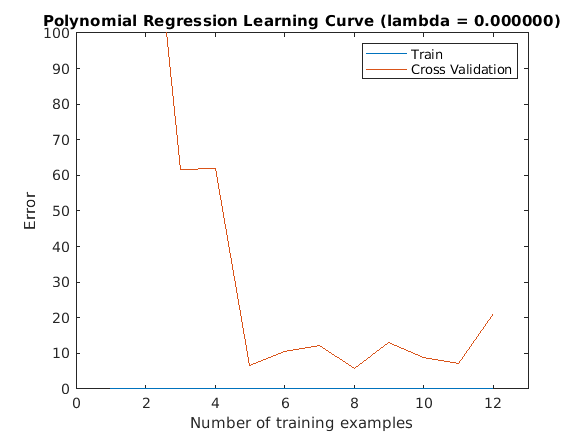

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

% Plot training data and fit

Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 7.866613e+00
Iteration     5 | Cost: 7.769329e+00
Iteration     6 | Cost: 7.634115e+00
Iteration     7 | Cost: 7.589488e+00
Iteration     8 | Cost: 7.415950e+00
Iteration     9 | Cost: 7.387292e+00
Iteration    10 | Cost: 7.347892e+00
Iteration    11 | Cost: 7.341983e+00
Iteration    12 | Cost: 7.297080e+00
Iteration    13 | Cost: 7.272002e+00
Iteration    14 | Cost: 7.268800e+00
Iteration    15 | Cost: 7.268650e+00
Iteration    16 | Cost: 7.268285e+00
Iteration    17 | Cost: 7.268247e+00
Iteration    18 | Cost: 7.268214e+00
Iteration    19 | Cost: 7.268200e+00
Iteration    20 | Cost: 7.268182e+00
Iteration    21 | Cost: 7.268162e+00
Iteration    22 | Cost: 7.268158e+00
Iteration    23 | Cost: 7.268153e+00
Iteration    24 | Cost: 7.268152e+00
Iteration    25 | Cost: 7.268150e+00
Iteration    26 | Cost: 7.268150e+00
Iteration    27 | Cost: 7.268149e+00
I

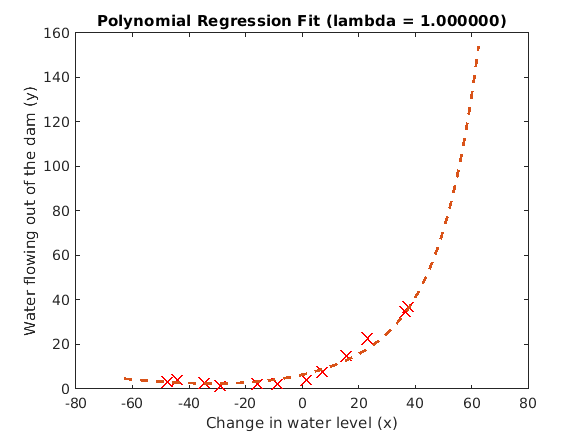

plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));

Dataset size: 1
Lambda Value:1.000000
Iteration     1 | Cost: 5.280051e-01
Iteration     2 | Cost: 2.083531e-01
Iteration     3 | Cost: 9.810873e-02
Iteration     4 | Cost: 1.501116e-03
Iteration     5 | Cost: 1.089480e-03
Iteration     6 | Cost: 4.451497e-31
Iteration     7 | Cost: 3.829364e-31
Iteration     8 | Cost: 1.258474e-31
Iteration     9 | Cost: 1.098718e-31


theta =     2.1343
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


*********************************************************************************
Dataset size: 2
Lambda Value:1.000000
Iteration     1 | Cost: 2.032751e-01
Iteration     2 | Cost: 1.041953e-01
Iteration     3 | Cost: 7.367762e-02
Iteration     4 | Cost: 7.279642e-02
Iteration     5 | Cost: 7.269797e-02
Iteration     6 | Cost: 7.269533e-02
Iteration     7 | Cost: 7.269502e-02
Iteration     8 | Cost: 7.269437e-02
Iteration     9 | Cost: 7.269436e-02
Iteration    10 | Cost: 7.269436e-02
Iteration    11 | Cost: 7.269436e-02
Iteration    12 | Cost: 7.269436e-02
Iteration    13 | Cost: 7.269436e-02
Iteration    14 | Cost: 7.269436e-02
Iteration    15 | Cost: 7.269436e-02
Iteration    16 | Cost: 7.269436e-02
Iteration    17 | Cost: 7.269436e-02
Iteration    18 | Cost: 7.269436e-02
Iteration    19 | Cost: 7.269436e-02
Iteration    20 | Cost: 7.269436e-02


theta =     1.5366
    0.1334
   -0.2288
    0.1302
   -0.1147
    0.0645
   -0.0469
    0.0270
   -0.0180


*********************************************************************************
Dataset size: 3
Lambda Value:1.000000
Iteration     1 | Cost: 3.958682e+01
Iteration     2 | Cost: 2.172738e+01
Iteration     3 | Cost: 2.007128e+01
Iteration     4 | Cost: 1.908475e+01
Iteration     5 | Cost: 1.903782e+01
Iteration     6 | Cost: 1.872107e+01
Iteration     7 | Cost: 1.855211e+01
Iteration     8 | Cost: 1.852112e+01
Iteration     9 | Cost: 1.850029e+01
Iteration    10 | Cost: 1.849891e+01
Iteration    11 | Cost: 1.849887e+01
Iteration    12 | Cost: 1.849879e+01
Iteration    13 | Cost: 1.849879e+01
Iteration    14 | Cost: 1.849879e+01
Iteration    15 | Cost: 1.849879e+01
Iteration    16 | Cost: 1.849879e+01
Iteration    17 | Cost: 1.849879e+01
Iteration    18 | Cost: 1.849879e+01
Iteration    19 | Cost: 1.849879e+01
Iteration    20 | Cost: 1.849879e+01
Iteration    21 | Cost: 1.849879e+01
Iteration    22 | Cost: 1.849879e+01
Iteration    23 | Cost: 1.849879e+01
Iteration    24 | Cost: 1.849

theta =    10.4295
    6.5586
    3.4554
    4.2571
    2.6837
    2.5951
    1.7423
    1.5311
    1.0632


*********************************************************************************
Dataset size: 4
Lambda Value:1.000000
Iteration     1 | Cost: 1.883439e+01
Iteration     2 | Cost: 1.695119e+01
Iteration     3 | Cost: 1.546680e+01
Iteration     4 | Cost: 1.486258e+01
Iteration     5 | Cost: 1.462699e+01
Iteration     6 | Cost: 1.460173e+01
Iteration     7 | Cost: 1.458789e+01
Iteration     8 | Cost: 1.458160e+01
Iteration     9 | Cost: 1.457865e+01
Iteration    10 | Cost: 1.457604e+01
Iteration    11 | Cost: 1.457595e+01
Iteration    12 | Cost: 1.457591e+01
Iteration    13 | Cost: 1.457590e+01
Iteration    14 | Cost: 1.457588e+01
Iteration    15 | Cost: 1.457587e+01
Iteration    16 | Cost: 1.457586e+01
Iteration    17 | Cost: 1.457586e+01
Iteration    18 | Cost: 1.457586e+01
Iteration    19 | Cost: 1.457586e+01
Iteration    20 | Cost: 1.457586e+01
Iteration    21 | Cost: 1.457586e+01
Iteration    22 | Cost: 1.457586e+01
Iteration    23 | Cost: 1.457586e+01
Iteration    24 | Cost: 1.457

theta =    10.8907
    6.7348
    3.6769
    4.5100
    2.9536
    2.8468
    1.9864
    1.7437
    1.2568


*********************************************************************************
Dataset size: 5
Lambda Value:1.000000
Iteration     1 | Cost: 9.507932e+01
Iteration     2 | Cost: 3.745281e+01
Iteration     3 | Cost: 1.603853e+01
Iteration     4 | Cost: 1.259101e+01
Iteration     5 | Cost: 1.224802e+01
Iteration     6 | Cost: 1.203685e+01
Iteration     7 | Cost: 1.177170e+01
Iteration     8 | Cost: 1.170342e+01
Iteration     9 | Cost: 1.167415e+01
Iteration    10 | Cost: 1.166568e+01
Iteration    11 | Cost: 1.166403e+01
Iteration    12 | Cost: 1.166165e+01
Iteration    13 | Cost: 1.166154e+01
Iteration    14 | Cost: 1.166139e+01
Iteration    15 | Cost: 1.166100e+01
Iteration    16 | Cost: 1.166088e+01
Iteration    17 | Cost: 1.166075e+01
Iteration    18 | Cost: 1.166074e+01
Iteration    19 | Cost: 1.166073e+01
Iteration    20 | Cost: 1.166073e+01
Iteration    21 | Cost: 1.166072e+01
Iteration    22 | Cost: 1.166072e+01
Iteration    23 | Cost: 1.166072e+01
Iteration    24 | Cost: 1.166

theta =    10.8770
    6.7354
    3.6750
    4.5132
    2.9487
    2.8522
    1.9799
    1.7503
    1.2496


*********************************************************************************
Dataset size: 6
Lambda Value:1.000000
Iteration     1 | Cost: 7.115385e+01
Iteration     2 | Cost: 2.111452e+01
Iteration     3 | Cost: 1.314175e+01
Iteration     4 | Cost: 1.054644e+01
Iteration     5 | Cost: 1.036773e+01
Iteration     6 | Cost: 1.034120e+01
Iteration     7 | Cost: 1.026977e+01
Iteration     8 | Cost: 1.022714e+01
Iteration     9 | Cost: 1.019759e+01
Iteration    10 | Cost: 1.015385e+01
Iteration    11 | Cost: 1.014049e+01
Iteration    12 | Cost: 1.013163e+01
Iteration    13 | Cost: 1.013124e+01
Iteration    14 | Cost: 1.012855e+01
Iteration    15 | Cost: 1.012593e+01
Iteration    16 | Cost: 1.011958e+01
Iteration    17 | Cost: 1.011929e+01
Iteration    18 | Cost: 1.011892e+01
Iteration    19 | Cost: 1.011888e+01
Iteration    20 | Cost: 1.011885e+01
Iteration    21 | Cost: 1.011883e+01
Iteration    22 | Cost: 1.011882e+01
Iteration    23 | Cost: 1.011882e+01
Iteration    24 | Cost: 1.011

theta =    10.1905
    6.5116
    4.4218
    4.5250
    3.1365
    3.0210
    1.9522
    1.9624
    1.1301


*********************************************************************************
Dataset size: 7
Lambda Value:1.000000
Iteration     1 | Cost: 7.518060e+01
Iteration     2 | Cost: 1.382098e+01
Iteration     3 | Cost: 1.013585e+01
Iteration     4 | Cost: 9.951504e+00
Iteration     5 | Cost: 9.882240e+00
Iteration     6 | Cost: 9.649782e+00
Iteration     7 | Cost: 9.525777e+00
Iteration     8 | Cost: 9.449554e+00
Iteration     9 | Cost: 9.447510e+00
Iteration    10 | Cost: 9.429921e+00
Iteration    11 | Cost: 9.425455e+00
Iteration    12 | Cost: 9.419740e+00
Iteration    13 | Cost: 9.417907e+00
Iteration    14 | Cost: 9.417501e+00
Iteration    15 | Cost: 9.416908e+00
Iteration    16 | Cost: 9.416845e+00
Iteration    17 | Cost: 9.416670e+00
Iteration    18 | Cost: 9.416603e+00
Iteration    19 | Cost: 9.416428e+00
Iteration    20 | Cost: 9.416377e+00
Iteration    21 | Cost: 9.416326e+00
Iteration    22 | Cost: 9.416324e+00
Iteration    23 | Cost: 9.416321e+00
Iteration    24 | Cost: 9.416

theta =    10.9237
    7.6554
    3.8984
    4.0432
    2.7162
    2.4767
    1.7531
    1.5295
    1.0868


*********************************************************************************
Dataset size: 8
Lambda Value:1.000000
Iteration     1 | Cost: 6.611004e+01
Iteration     2 | Cost: 1.227749e+01
Iteration     3 | Cost: 1.079462e+01
Iteration     4 | Cost: 8.838726e+00
Iteration     5 | Cost: 8.699382e+00
Iteration     6 | Cost: 8.507287e+00
Iteration     7 | Cost: 8.364305e+00
Iteration     8 | Cost: 8.333738e+00
Iteration     9 | Cost: 8.291157e+00
Iteration    10 | Cost: 8.288967e+00
Iteration    11 | Cost: 8.279162e+00
Iteration    12 | Cost: 8.274785e+00
Iteration    13 | Cost: 8.265375e+00
Iteration    14 | Cost: 8.258230e+00
Iteration    15 | Cost: 8.257980e+00
Iteration    16 | Cost: 8.257039e+00
Iteration    17 | Cost: 8.256708e+00
Iteration    18 | Cost: 8.256325e+00
Iteration    19 | Cost: 8.256301e+00
Iteration    20 | Cost: 8.256290e+00
Iteration    21 | Cost: 8.256253e+00
Iteration    22 | Cost: 8.256243e+00
Iteration    23 | Cost: 8.256231e+00
Iteration    24 | Cost: 8.256

theta =    10.9980
    7.5756
    4.0258
    3.9578
    2.7508
    2.4717
    1.7000
    1.5989
    0.9739


*********************************************************************************
Dataset size: 9
Lambda Value:1.000000
Iteration     1 | Cost: 6.224886e+01
Iteration     2 | Cost: 1.073478e+01
Iteration     3 | Cost: 9.717384e+00
Iteration     4 | Cost: 8.288207e+00
Iteration     5 | Cost: 7.998823e+00
Iteration     6 | Cost: 7.942762e+00
Iteration     7 | Cost: 7.861286e+00
Iteration     8 | Cost: 7.844122e+00
Iteration     9 | Cost: 7.832684e+00
Iteration    10 | Cost: 7.805486e+00
Iteration    11 | Cost: 7.802105e+00
Iteration    12 | Cost: 7.802094e+00
Iteration    13 | Cost: 7.802080e+00
Iteration    14 | Cost: 7.802079e+00
Iteration    15 | Cost: 7.802078e+00
Iteration    16 | Cost: 7.802077e+00
Iteration    17 | Cost: 7.802077e+00
Iteration    18 | Cost: 7.802077e+00
Iteration    19 | Cost: 7.802077e+00
Iteration    20 | Cost: 7.802077e+00
Iteration    21 | Cost: 7.802076e+00
Iteration    22 | Cost: 7.802076e+00
Iteration    23 | Cost: 7.802076e+00
Iteration    24 | Cost: 7.802

theta =    10.5912
    7.3473
    4.6339
    4.0385
    2.7751
    2.5740
    1.6379
    1.7033
    0.8915


*********************************************************************************
Dataset size: 10
Lambda Value:1.000000
Iteration     1 | Cost: 5.861091e+01
Iteration     2 | Cost: 1.233951e+01
Iteration     3 | Cost: 1.172055e+01
Iteration     4 | Cost: 9.221113e+00
Iteration     5 | Cost: 8.122554e+00
Iteration     6 | Cost: 7.932984e+00
Iteration     7 | Cost: 7.313700e+00
Iteration     8 | Cost: 7.210498e+00
Iteration     9 | Cost: 7.185608e+00
Iteration    10 | Cost: 7.111784e+00
Iteration    11 | Cost: 7.086221e+00
Iteration    12 | Cost: 7.077356e+00
Iteration    13 | Cost: 7.067518e+00
Iteration    14 | Cost: 7.066544e+00
Iteration    15 | Cost: 7.065148e+00
Iteration    16 | Cost: 7.065042e+00
Iteration    17 | Cost: 7.064712e+00
Iteration    18 | Cost: 7.064563e+00
Iteration    19 | Cost: 7.064491e+00
Iteration    20 | Cost: 7.064412e+00
Iteration    21 | Cost: 7.064406e+00
Iteration    22 | Cost: 7.064402e+00
Iteration    23 | Cost: 7.064399e+00
Iteration    24 | Cost: 7.06

theta =    10.6842
    7.3447
    4.7111
    3.9310
    2.8775
    2.4998
    1.6461
    1.7476
    0.7563


*********************************************************************************
Dataset size: 11
Lambda Value:1.000000
Iteration     1 | Cost: 7.248552e+01
Iteration     2 | Cost: 2.583449e+01
Iteration     3 | Cost: 8.711534e+00
Iteration     4 | Cost: 6.790164e+00
Iteration     5 | Cost: 6.687293e+00
Iteration     6 | Cost: 6.663962e+00
Iteration     7 | Cost: 6.595243e+00
Iteration     8 | Cost: 6.538932e+00
Iteration     9 | Cost: 6.513460e+00
Iteration    10 | Cost: 6.477429e+00
Iteration    11 | Cost: 6.451620e+00
Iteration    12 | Cost: 6.449203e+00
Iteration    13 | Cost: 6.428503e+00
Iteration    14 | Cost: 6.426517e+00
Iteration    15 | Cost: 6.424335e+00
Iteration    16 | Cost: 6.424266e+00
Iteration    17 | Cost: 6.424039e+00
Iteration    18 | Cost: 6.423949e+00
Iteration    19 | Cost: 6.423880e+00
Iteration    20 | Cost: 6.423857e+00
Iteration    21 | Cost: 6.423835e+00
Iteration    22 | Cost: 6.423806e+00
Iteration    23 | Cost: 6.423802e+00
Iteration    24 | Cost: 6.42

theta =    10.6627
    7.3215
    4.7348
    3.9438
    2.8820
    2.5101
    1.6466
    1.7546
    0.7562


*********************************************************************************
Dataset size: 12
Lambda Value:1.000000
Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 7.866613e+00
Iteration     5 | Cost: 7.769329e+00
Iteration     6 | Cost: 7.634115e+00
Iteration     7 | Cost: 7.589488e+00
Iteration     8 | Cost: 7.415950e+00
Iteration     9 | Cost: 7.387292e+00
Iteration    10 | Cost: 7.347892e+00
Iteration    11 | Cost: 7.341983e+00
Iteration    12 | Cost: 7.297080e+00
Iteration    13 | Cost: 7.272002e+00
Iteration    14 | Cost: 7.268800e+00
Iteration    15 | Cost: 7.268650e+00
Iteration    16 | Cost: 7.268285e+00
Iteration    17 | Cost: 7.268247e+00
Iteration    18 | Cost: 7.268214e+00
Iteration    19 | Cost: 7.268200e+00
Iteration    20 | Cost: 7.268182e+00
Iteration    21 | Cost: 7.268162e+00
Iteration    22 | Cost: 7.268158e+00
Iteration    23 | Cost: 7.268153e+00
Iteration    24 | Cost: 7.26

theta =    11.2176
    8.5852
    5.2127
    3.5911
    2.2830
    1.7603
    1.0681
    1.1076
    0.3940


*********************************************************************************


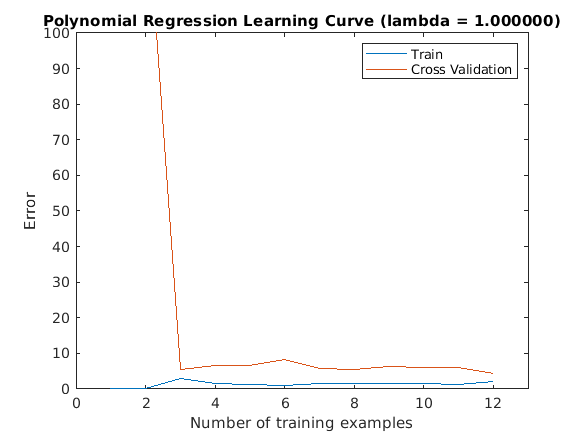

xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

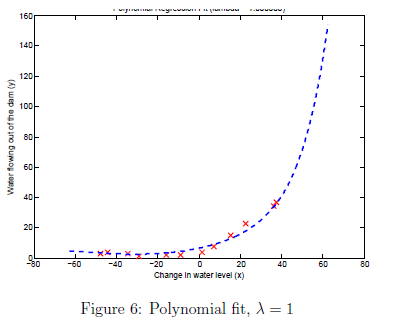

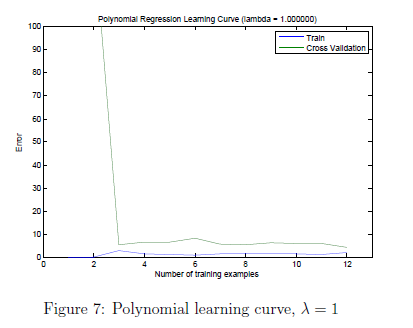

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

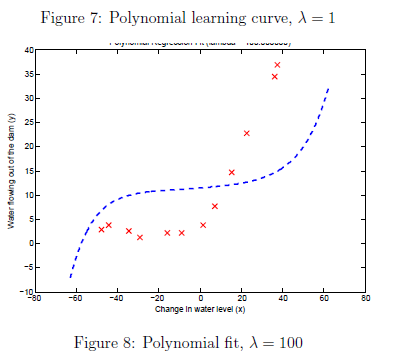

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411543e-01
Iteration    11 | Cost: 7.963444e-01
Iteration    12 | Cost: 7.528112e-01
Iteration    13 | Cost: 6.880751e-01
Iteration    14 | Cost: 5.714607e-01
Iteration    15 | Cost: 5.378361e-01
Iteration    16 | Cost: 4.500706e-01
Iteration    17 | Cost: 4.476781e-01
Iteration    18 | Cost: 4.323836e-01
Iteration    19 | Cost: 3.753054e-01
Iteration    20 | Cost: 3.694780e-01
Iteration    21 | Cost: 3.575323e-01
Iteration    22 | Cost: 3.527283e-01
Iteration    23 | Cost: 3.404259e-01
Iteration    24 | Cost: 3.397391e-01
Iteration    25 | Cost: 3.385740e-01
Iteration    26 | Cost: 3.342204e-01
Iteration    27 | Cost: 3.319424e-01
I

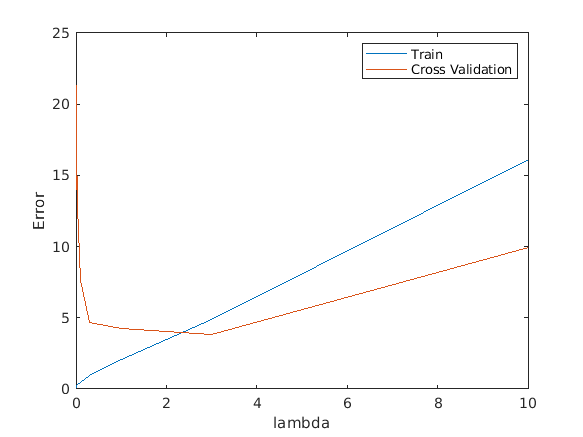

for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end

    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

lambda		Train Error	Validation Error


0.000000	0.176944	21.343808
0.001000	0.139607	14.041361
0.003000	0.174565	17.073179
0.010000	0.223199	17.088109
0.030000	0.281869	12.831604
0.100000	0.459318	7.587014
0.300000	0.921760	4.636833
1.000000	2.076188	4.260625
3.000000	4.901351	3.822907
10.000000	16.092213	9.945508


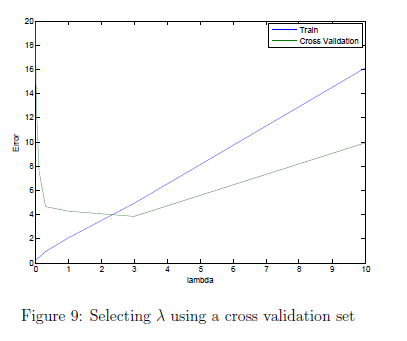

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

Dataset size: 1
Lambda Value:0.010000
Iteration     1 | Cost: 3.405390e-01
Iteration     2 | Cost: 4.988078e-03
Iteration     3 | Cost: 2.151804e-04
Iteration     4 | Cost: 1.111526e-04
Iteration     5 | Cost: 5.971823e-05
Iteration     6 | Cost: 1.149113e-06
Iteration     7 | Cost: 1.118191e-06
Iteration     8 | Cost: 5.589559e-07
Iteration     9 | Cost: 2.324464e-08
Iteration    10 | Cost: 2.323681e-08
Iteration    11 | Cost: 2.302666e-08
Iteration    12 | Cost: 1.565767e-09
Iteration    13 | Cost: 1.565301e-09
Iteration    14 | Cost: 1.550797e-09
Iteration    15 | Cost: 1.155014e-09
Iteration    16 | Cost: 3.935449e-11
Iteration    17 | Cost: 7.973210e-12
Iteration    18 | Cost: 3.407584e-12
Iteration    19 | Cost: 3.935525e-13
Iteration    20 | Cost: 1.649361e-14
Iteration    21 | Cost: 4.690652e-15
Iteration    22 | Cost: 6.854626e-18
Iteration    23 | Cost: 6.829517e-18
Iteration    24 | Cost: 6.793342e-18
Iteration    25 | Cost: 6.629255e-18
Iteration    26 | Cost: 4.750809e-18


theta =     2.1343
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000


*********************************************************************************
Dataset size: 2
Lambda Value:0.010000
Iteration     1 | Cost: 5.523568e-02
Iteration     2 | Cost: 3.367312e-03
Iteration     3 | Cost: 3.037007e-03
Iteration     4 | Cost: 2.999639e-03
Iteration     5 | Cost: 2.990979e-03
Iteration     6 | Cost: 2.336617e-03
Iteration     7 | Cost: 2.123237e-03
Iteration     8 | Cost: 1.936561e-03
Iteration     9 | Cost: 1.936559e-03
Iteration    10 | Cost: 1.934948e-03
Iteration    11 | Cost: 1.934845e-03
Iteration    12 | Cost: 1.934800e-03
Iteration    13 | Cost: 1.933872e-03
Iteration    14 | Cost: 1.932846e-03
Iteration    15 | Cost: 1.930444e-03
Iteration    16 | Cost: 1.930286e-03
Iteration    17 | Cost: 1.930061e-03
Iteration    18 | Cost: 1.930051e-03
Iteration    19 | Cost: 1.930045e-03
Iteration    20 | Cost: 1.930039e-03
Iteration    21 | Cost: 1.930039e-03
Iteration    22 | Cost: 1.930039e-03
Iteration    23 | Cost: 1.930038e-03
Iteration    24 | Cost: 1.930

theta =     1.3427
    0.3543
   -0.6076
    0.3455
   -0.3046
    0.1713
   -0.1246
    0.0716
   -0.0479


*********************************************************************************
Dataset size: 3
Lambda Value:0.010000
Iteration     1 | Cost: 3.032734e+01
Iteration     2 | Cost: 1.226927e+00
Iteration     3 | Cost: 7.383164e-01
Iteration     4 | Cost: 2.727993e-01
Iteration     5 | Cost: 2.622976e-01
Iteration     6 | Cost: 2.616915e-01
Iteration     7 | Cost: 2.612460e-01
Iteration     8 | Cost: 2.600987e-01
Iteration     9 | Cost: 2.597820e-01
Iteration    10 | Cost: 2.293193e-01
Iteration    11 | Cost: 2.245222e-01
Iteration    12 | Cost: 2.233166e-01
Iteration    13 | Cost: 2.216354e-01
Iteration    14 | Cost: 2.211828e-01
Iteration    15 | Cost: 2.208628e-01
Iteration    16 | Cost: 2.207706e-01
Iteration    17 | Cost: 2.207157e-01
Iteration    18 | Cost: 2.206993e-01
Iteration    19 | Cost: 2.206900e-01
Iteration    20 | Cost: 2.206839e-01
Iteration    21 | Cost: 2.206780e-01
Iteration    22 | Cost: 2.206654e-01
Iteration    23 | Cost: 2.206531e-01
Iteration    24 | Cost: 2.206

theta =    10.3722
    7.5519
    4.6101
    4.8100
    3.4476
    2.9634
    2.1801
    1.7719
    1.3079


*********************************************************************************
Dataset size: 4
Lambda Value:0.010000
Iteration     1 | Cost: 9.871955e-01
Iteration     2 | Cost: 3.772825e-01
Iteration     3 | Cost: 2.193567e-01
Iteration     4 | Cost: 1.925157e-01
Iteration     5 | Cost: 1.805322e-01
Iteration     6 | Cost: 1.737281e-01
Iteration     7 | Cost: 1.698168e-01
Iteration     8 | Cost: 1.698001e-01
Iteration     9 | Cost: 1.697665e-01
Iteration    10 | Cost: 1.696779e-01
Iteration    11 | Cost: 1.696638e-01
Iteration    12 | Cost: 1.691695e-01
Iteration    13 | Cost: 1.691657e-01
Iteration    14 | Cost: 1.691603e-01
Iteration    15 | Cost: 1.691490e-01
Iteration    16 | Cost: 1.691438e-01
Iteration    17 | Cost: 1.691410e-01
Iteration    18 | Cost: 1.691401e-01
Iteration    19 | Cost: 1.691388e-01
Iteration    20 | Cost: 1.691370e-01
Iteration    21 | Cost: 1.691346e-01
Iteration    22 | Cost: 1.691328e-01
Iteration    23 | Cost: 1.691319e-01
Iteration    24 | Cost: 1.691

theta =    10.4686
    8.2460
    4.9300
    4.5512
    3.1371
    2.3884
    1.6155
    1.1610
    0.7408


*********************************************************************************
Dataset size: 5
Lambda Value:0.010000
Iteration     1 | Cost: 9.146884e+01
Iteration     2 | Cost: 2.771876e+01
Iteration     3 | Cost: 3.163820e+00
Iteration     4 | Cost: 1.640727e+00
Iteration     5 | Cost: 8.611581e-01
Iteration     6 | Cost: 3.396053e-01
Iteration     7 | Cost: 2.969970e-01
Iteration     8 | Cost: 2.350864e-01
Iteration     9 | Cost: 2.186501e-01
Iteration    10 | Cost: 2.104159e-01
Iteration    11 | Cost: 2.099113e-01
Iteration    12 | Cost: 2.035060e-01
Iteration    13 | Cost: 2.000292e-01
Iteration    14 | Cost: 1.966937e-01
Iteration    15 | Cost: 1.908756e-01
Iteration    16 | Cost: 1.858021e-01
Iteration    17 | Cost: 1.842571e-01
Iteration    18 | Cost: 1.780650e-01
Iteration    19 | Cost: 1.766002e-01
Iteration    20 | Cost: 1.744886e-01
Iteration    21 | Cost: 1.739410e-01
Iteration    22 | Cost: 1.722673e-01
Iteration    23 | Cost: 1.689694e-01
Iteration    24 | Cost: 1.665

theta =    10.4039
    8.2302
    4.9539
    4.5582
    3.1226
    2.4178
    1.5803
    1.2019
    0.6970


*********************************************************************************
Dataset size: 6
Lambda Value:0.010000
Iteration     1 | Cost: 6.690068e+01
Iteration     2 | Cost: 1.226122e+01
Iteration     3 | Cost: 1.918807e+00
Iteration     4 | Cost: 7.408589e-01
Iteration     5 | Cost: 3.343811e-01
Iteration     6 | Cost: 1.632769e-01
Iteration     7 | Cost: 1.622905e-01
Iteration     8 | Cost: 1.614093e-01
Iteration     9 | Cost: 1.607862e-01
Iteration    10 | Cost: 1.603900e-01
Iteration    11 | Cost: 1.595768e-01
Iteration    12 | Cost: 1.584787e-01
Iteration    13 | Cost: 1.578701e-01
Iteration    14 | Cost: 1.577441e-01
Iteration    15 | Cost: 1.574645e-01
Iteration    16 | Cost: 1.572548e-01
Iteration    17 | Cost: 1.568812e-01
Iteration    18 | Cost: 1.565099e-01
Iteration    19 | Cost: 1.562581e-01
Iteration    20 | Cost: 1.561069e-01
Iteration    21 | Cost: 1.558898e-01
Iteration    22 | Cost: 1.552093e-01
Iteration    23 | Cost: 1.548033e-01
Iteration    24 | Cost: 1.542

theta =     9.8183
    6.9071
    6.2527
    6.1483
    2.0909
    2.9117
    1.4448
    0.4708
    1.2502


*********************************************************************************
Dataset size: 7
Lambda Value:0.010000
Iteration     1 | Cost: 7.111306e+01
Iteration     2 | Cost: 4.803470e+00
Iteration     3 | Cost: 2.620374e+00
Iteration     4 | Cost: 1.535053e+00
Iteration     5 | Cost: 1.291423e+00
Iteration     6 | Cost: 7.629676e-01
Iteration     7 | Cost: 2.958943e-01
Iteration     8 | Cost: 2.538842e-01
Iteration     9 | Cost: 2.536628e-01
Iteration    10 | Cost: 2.509580e-01
Iteration    11 | Cost: 2.491922e-01
Iteration    12 | Cost: 2.488931e-01
Iteration    13 | Cost: 2.470797e-01
Iteration    14 | Cost: 2.465594e-01
Iteration    15 | Cost: 2.443735e-01
Iteration    16 | Cost: 2.442921e-01
Iteration    17 | Cost: 2.440353e-01
Iteration    18 | Cost: 2.438727e-01
Iteration    19 | Cost: 2.433453e-01
Iteration    20 | Cost: 2.433309e-01
Iteration    21 | Cost: 2.432725e-01
Iteration    22 | Cost: 2.432346e-01
Iteration    23 | Cost: 2.431736e-01
Iteration    24 | Cost: 2.430

theta =    11.1691
   12.3702
    7.4992
    0.1988
   -0.6243
    1.1322
    0.2956
    1.4480
    1.1313


*********************************************************************************
Dataset size: 8
Lambda Value:0.010000
Iteration     1 | Cost: 6.237381e+01
Iteration     2 | Cost: 3.552163e+00
Iteration     3 | Cost: 2.478752e+00
Iteration     4 | Cost: 1.584286e+00
Iteration     5 | Cost: 1.429355e+00
Iteration     6 | Cost: 1.336900e+00
Iteration     7 | Cost: 1.282989e+00
Iteration     8 | Cost: 1.127551e+00
Iteration     9 | Cost: 1.027106e+00
Iteration    10 | Cost: 8.902896e-01
Iteration    11 | Cost: 7.959456e-01
Iteration    12 | Cost: 7.241146e-01
Iteration    13 | Cost: 6.796701e-01
Iteration    14 | Cost: 6.179024e-01
Iteration    15 | Cost: 5.985929e-01
Iteration    16 | Cost: 5.725277e-01
Iteration    17 | Cost: 5.644277e-01
Iteration    18 | Cost: 5.360088e-01
Iteration    19 | Cost: 4.383897e-01
Iteration    20 | Cost: 3.908645e-01
Iteration    21 | Cost: 3.619816e-01
Iteration    22 | Cost: 3.375028e-01
Iteration    23 | Cost: 3.026970e-01
Iteration    24 | Cost: 2.911

theta =    11.3440
   12.5773
    6.9752
   -0.4123
    0.9372
    0.4713
    0.6651
    2.2630
   -0.3779


*********************************************************************************
Dataset size: 9
Lambda Value:0.010000
Iteration     1 | Cost: 5.925570e+01
Iteration     2 | Cost: 5.921196e+00
Iteration     3 | Cost: 5.367056e+00
Iteration     4 | Cost: 2.959075e+00
Iteration     5 | Cost: 2.150381e+00
Iteration     6 | Cost: 1.675967e+00
Iteration     7 | Cost: 1.448626e+00
Iteration     8 | Cost: 1.394538e+00
Iteration     9 | Cost: 1.326821e+00
Iteration    10 | Cost: 1.101456e+00
Iteration    11 | Cost: 9.728368e-01
Iteration    12 | Cost: 9.574580e-01
Iteration    13 | Cost: 8.459350e-01
Iteration    14 | Cost: 7.251819e-01
Iteration    15 | Cost: 6.848459e-01
Iteration    16 | Cost: 5.841443e-01
Iteration    17 | Cost: 5.723639e-01
Iteration    18 | Cost: 5.600945e-01
Iteration    19 | Cost: 5.469445e-01
Iteration    20 | Cost: 5.302428e-01
Iteration    21 | Cost: 5.245191e-01
Iteration    22 | Cost: 5.224511e-01
Iteration    23 | Cost: 5.028226e-01
Iteration    24 | Cost: 4.927

theta =    10.9752
   11.8278
   10.9084
    2.6579
   -4.1697
   -1.0319
   -0.1491
    0.1550
    0.7343


*********************************************************************************
Dataset size: 10
Lambda Value:0.010000
Iteration     1 | Cost: 5.601835e+01
Iteration     2 | Cost: 7.494332e+00
Iteration     3 | Cost: 6.661264e+00
Iteration     4 | Cost: 3.449824e+00
Iteration     5 | Cost: 2.319918e+00
Iteration     6 | Cost: 2.272745e+00
Iteration     7 | Cost: 1.639114e+00
Iteration     8 | Cost: 1.419241e+00
Iteration     9 | Cost: 1.347500e+00
Iteration    10 | Cost: 1.315435e+00
Iteration    11 | Cost: 9.432403e-01
Iteration    12 | Cost: 8.917642e-01
Iteration    13 | Cost: 8.236521e-01
Iteration    14 | Cost: 7.989068e-01
Iteration    15 | Cost: 7.685599e-01
Iteration    16 | Cost: 6.753424e-01
Iteration    17 | Cost: 6.662061e-01
Iteration    18 | Cost: 6.366495e-01
Iteration    19 | Cost: 6.206843e-01
Iteration    20 | Cost: 5.556087e-01
Iteration    21 | Cost: 5.476428e-01
Iteration    22 | Cost: 5.203736e-01
Iteration    23 | Cost: 5.044648e-01
Iteration    24 | Cost: 4.80

theta =    11.0622
   11.9035
   10.2408
    2.9762
   -2.8539
   -2.1670
    0.9107
    0.5152
   -1.2754


*********************************************************************************
Dataset size: 11
Lambda Value:0.010000
Iteration     1 | Cost: 7.187496e+01
Iteration     2 | Cost: 2.281183e+01
Iteration     3 | Cost: 5.007884e+00
Iteration     4 | Cost: 1.413732e+00
Iteration     5 | Cost: 1.311430e+00
Iteration     6 | Cost: 1.246468e+00
Iteration     7 | Cost: 1.216766e+00
Iteration     8 | Cost: 1.098592e+00
Iteration     9 | Cost: 9.723112e-01
Iteration    10 | Cost: 9.573635e-01
Iteration    11 | Cost: 8.960350e-01
Iteration    12 | Cost: 8.713736e-01
Iteration    13 | Cost: 8.684749e-01
Iteration    14 | Cost: 7.750754e-01
Iteration    15 | Cost: 6.751317e-01
Iteration    16 | Cost: 5.355007e-01
Iteration    17 | Cost: 5.131307e-01
Iteration    18 | Cost: 5.001036e-01
Iteration    19 | Cost: 4.807539e-01
Iteration    20 | Cost: 4.559561e-01
Iteration    21 | Cost: 4.430082e-01
Iteration    22 | Cost: 4.414209e-01
Iteration    23 | Cost: 4.392783e-01
Iteration    24 | Cost: 4.36

theta =    11.0248
   11.7350
   10.3845
    3.3775
   -2.8527
   -2.2551
    0.7134
    0.2140
   -1.3269


*********************************************************************************
Dataset size: 12
Lambda Value:0.010000
Iteration     1 | Cost: 8.273556e+01
Iteration     2 | Cost: 2.689698e+01
Iteration     3 | Cost: 1.330795e+01
Iteration     4 | Cost: 3.522725e+00
Iteration     5 | Cost: 2.931455e+00
Iteration     6 | Cost: 2.460864e+00
Iteration     7 | Cost: 2.422567e+00
Iteration     8 | Cost: 1.965447e+00
Iteration     9 | Cost: 1.836749e+00
Iteration    10 | Cost: 1.314161e+00
Iteration    11 | Cost: 9.760509e-01
Iteration    12 | Cost: 8.264676e-01
Iteration    13 | Cost: 6.261885e-01
Iteration    14 | Cost: 6.244717e-01
Iteration    15 | Cost: 6.140011e-01
Iteration    16 | Cost: 5.693037e-01
Iteration    17 | Cost: 5.674388e-01
Iteration    18 | Cost: 5.646812e-01
Iteration    19 | Cost: 5.611517e-01
Iteration    20 | Cost: 5.546674e-01
Iteration    21 | Cost: 5.449814e-01
Iteration    22 | Cost: 5.353451e-01
Iteration    23 | Cost: 5.270455e-01
Iteration    24 | Cost: 5.21

theta =    11.2176
   12.2102
   12.3564
    5.7131
   -4.4635
   -4.7738
   -0.9247
   -2.2338
   -2.3810


*********************************************************************************


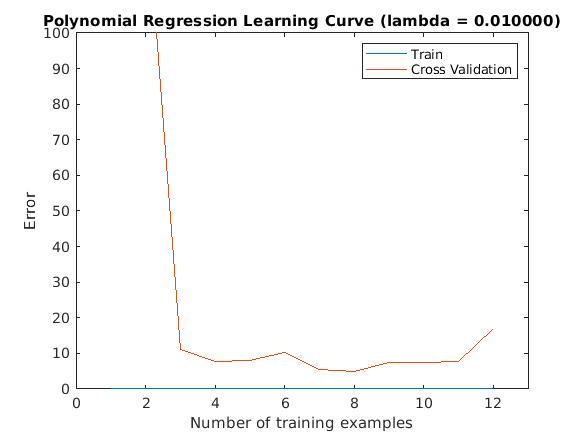

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

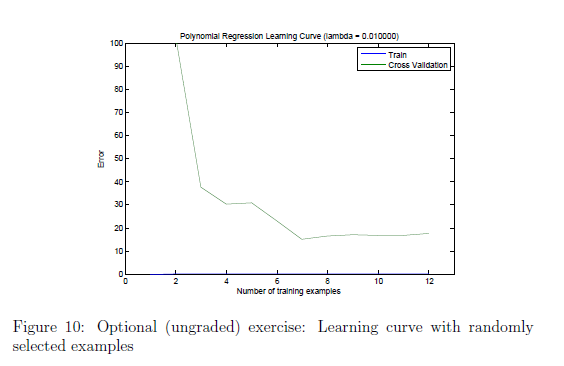

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

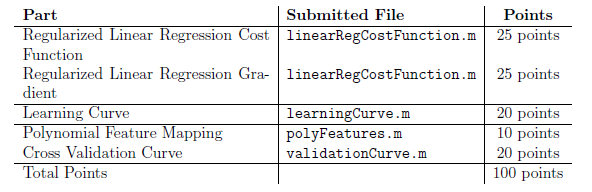

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.


.                        ex5_companion.mlx        fmincg.m                 linearRegCostFunction.m  submit.m                 
..                       ex5data1.mat             learningCurve.m          plotFit.m                trainLinearReg.m         
ex5.mlx                  featureNormalize.m       lib                      polyFeatures.m           validationCurve.m        

